# EEE 321 - Signals and Systems - Lab 3 - Tuna Şahin 22201730

## Beethoven - Symphony no. 7, I movement | Odeon Simulation

## Odeon's Impulse Response, Recording Part:

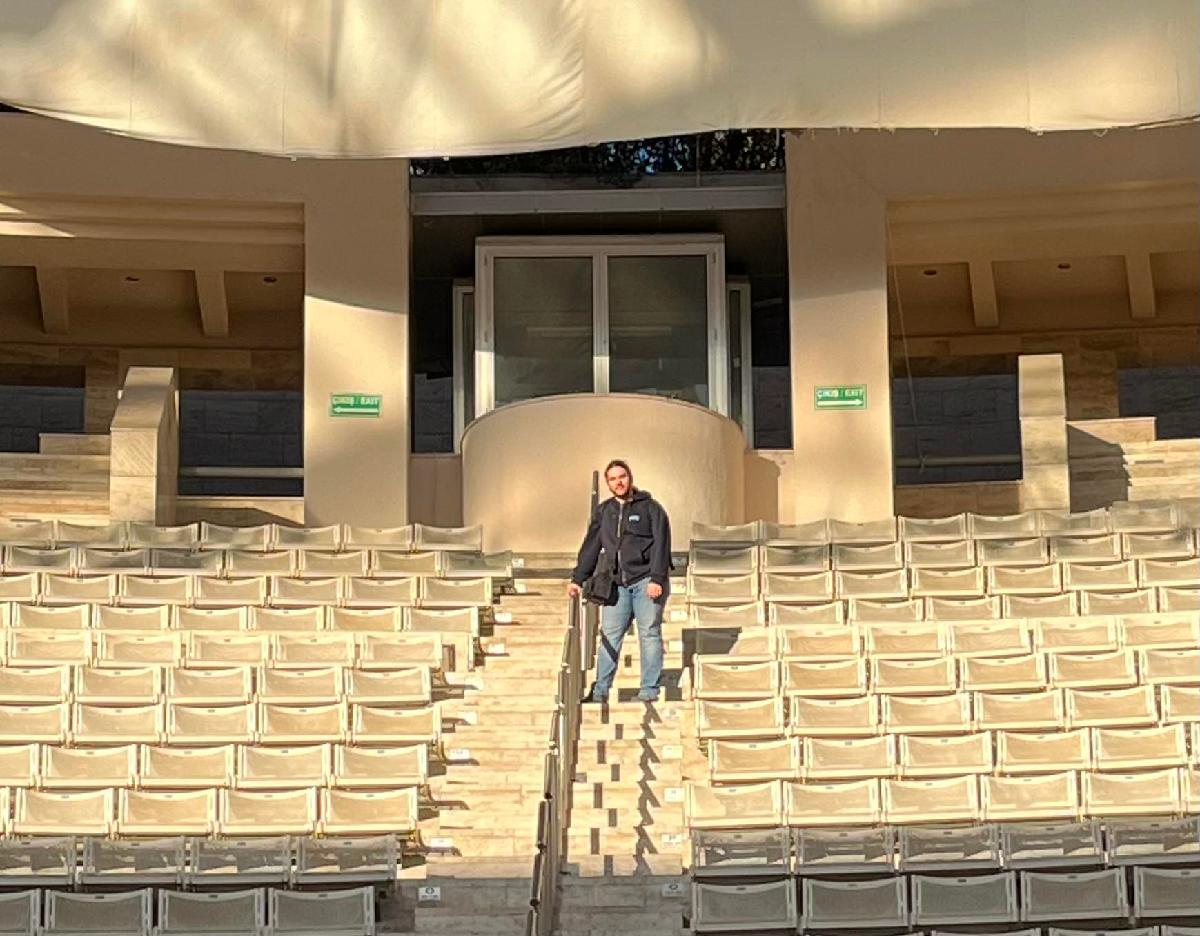       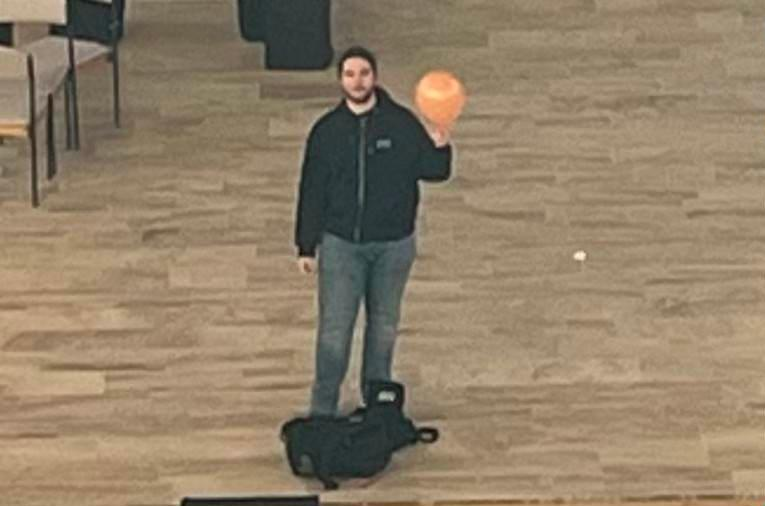

Figure 1: Me, waiting to record.                                      Figure 2: Me, about to pop a balloon.

## Technical Part:

The computation is done in 4 main parts, which are then plotted individually in subplots. The first part is the summing of all individual recordings. First we get a list of all mp3 files in the current directory, then we plot and sum all these recordings in a for loop.

subplot(2,2,1)
hold on
tracks = dir(fullfile(pwd, '**/*.mp3')); %get all mp3 files in current directory (everything except the tracks are .wav)
for i = 1:length(tracks) 
    [xn,Fs] = audioread(tracks(i).name,[1 inf],'double'); %read each track seperately
    if i == 1 %create the t array only once
        x = zeros([1 length(xn)]);
        tx = linspace(0,length(x)/Fs,length(x));
    end
    plot(tx,xn)
    x = x + xn.'; %combine all instrument tracks into a single channel
end
hold off
plot_config('Individual Recordings','t','x(t)',[-7 200],[-0.46 0.46],[1080 1080])

This second part plots the summed track and saves it as a .wav file with the name "Lab3Mixdown.wav".

subplot(2,2,2)
plot(tx,x)
audiowrite('Lab3Mixdown.wav',x.' * 0.7/max(x),Fs) %output the combined tracks into a seperate file for comparison, multiply with 8 for increased gain
plot_config('Mixed Recordings','t','x(t)',[-7 200],[-0.4 0.7],[1080 1080]) %plot the summed track 

The third part reads the impulse response from a .wav file and plots it.

subplot(2,2,3)
[h,Fs2] = audioread('impulse_response.wav',[1 inf],'double'); %read the impulse response from the file
th = linspace(0,length(h)/Fs,length(h));
plot(th,h) %plotting the impulse function
plot_config('Impulse Response','t','h(t)',[-0.1 4],[-0.5 0.5],[1080 1080])

The fourth and final part is where we filter the original recordings. The mixdown is convolved with the impulse response to simulate the Odeon environment. The result of the convolution is then exported into a file called "Lab3Filtered.wav". Another file called "Lab3Stereo.wav" is also created that contains the result in the left ear while it contains the original recording in the right ear for easy comparison between the two files. Lastly, we plot the result.

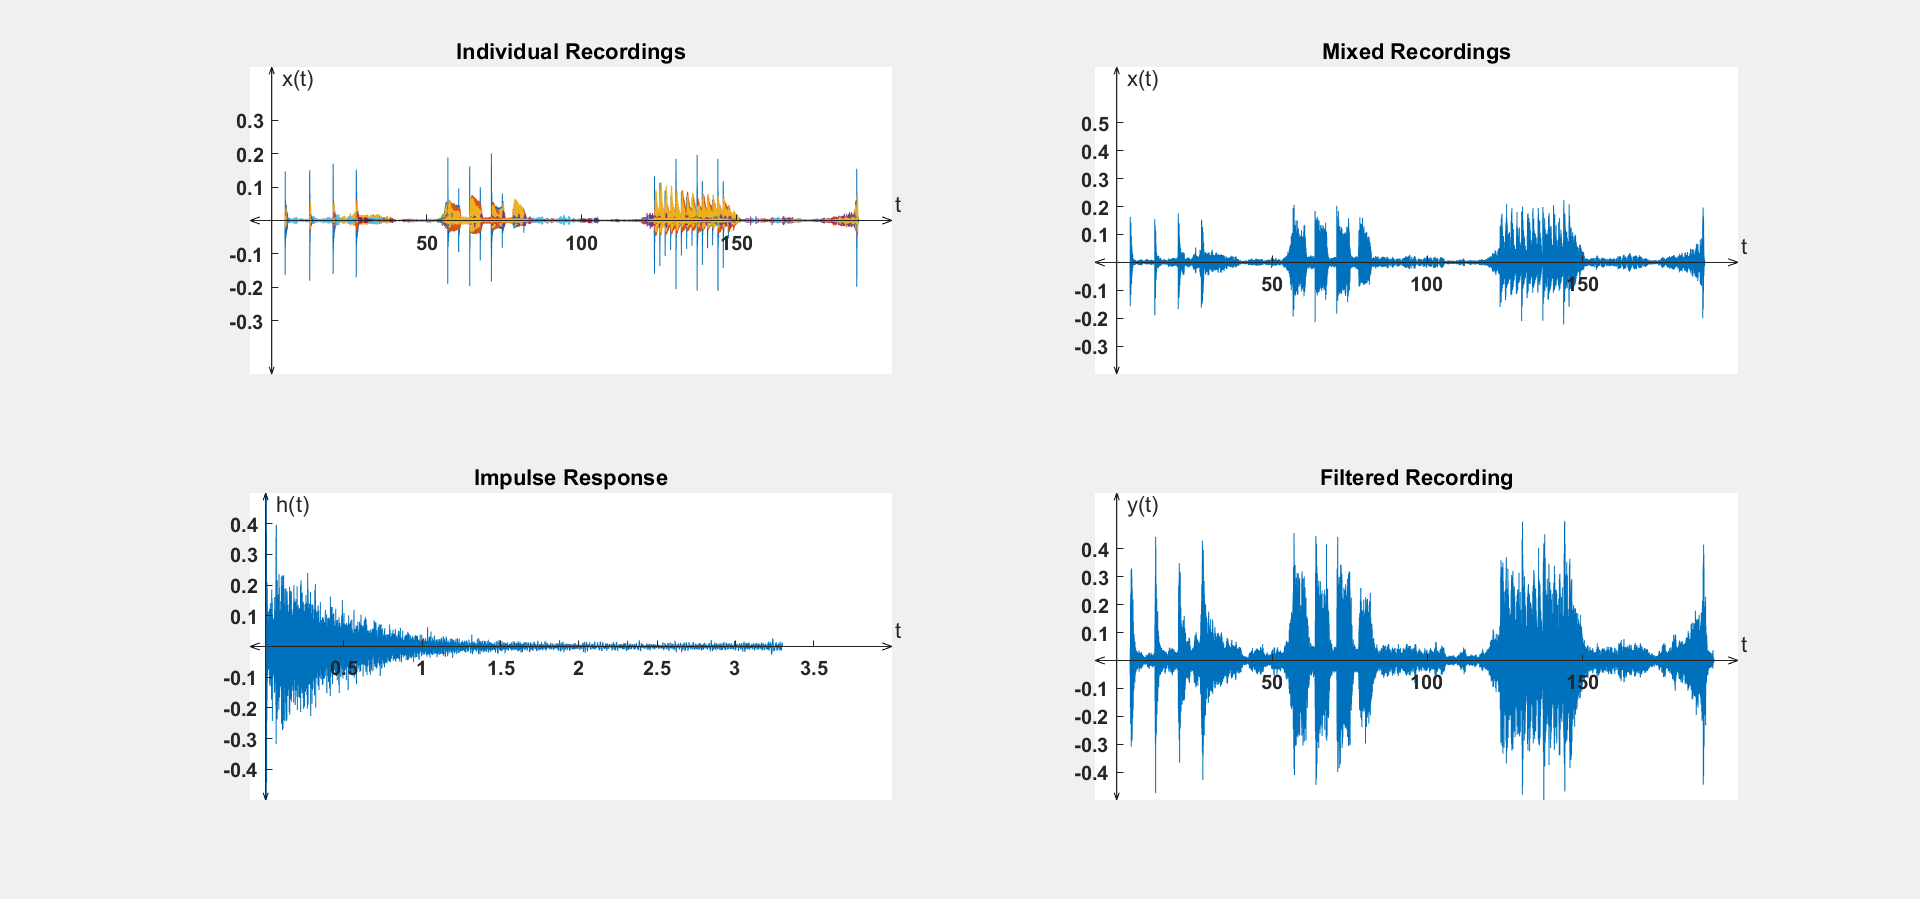

subplot(2,2,4)
y = conv(x,h); %convolve the impulse function with the mixed track
y = y * 0.5 / max(y); %normalise to prevent distortion, increase 0.5 to increase gain
audiowrite('Lab3Filtered.wav',y.',Fs) %save the mono recording to a file
audiowrite('lab3stereo.wav',[y(1:length(x)).' x.'],Fs) %save the recording as stereo: Left ear = output, Right ear = input
ty = linspace(0,length(y)/Fs,length(y));
plot(ty,y) %plot the final result
plot_config('Filtered Recording','t','y(t)',[-7 200],[-0.5 0.6],[1300 1080])
uicontrol('Visible','off') %this is to prevent a bug with plotting

##     Conclusion:

To address some possible issues during the process and some notes about the process itself:

- The impulse response was fairly clean. No bird or human sounds were present in the recording. However, a slight breeze is audible which can slightly temper with the results. We can assume this noise is negligible since if we look at the plot of the impulse function it is very minimal. 

- As a concept an impulse response alone specifies the response of a system to any input. We can then use this impulse response to simulate any signals as if they were playing inside Odeon itself.

- The Odeon as a system also has properties that would make it a non-LTI system. Some of these properties are temperature and speed of sound, the objects inside the Odeon that are being moved day-to-day and other similar factors. However, these factors can again considered to be negligible. The main factor that may change Odeon and its impulse response is the existance of an audience which will significantly decrease the echo in the system.

- There could also be distortions that are mostly caused while the arrays are being exported as .wav files. This can be prevented by dividing the entire array by a constant to reduce the maximum amplitude to somewhere around 0.5 ~ 0.7.

- As mentioned previously, there was a slight wind noise in audible in the recording. This was assumed to be negligible. However, other noises such as bird tweets or child noises (which were present due to the preschool next to Odeon) can cause a spike in the recording of the impulse response. These spikes may cause the echo to spike which would sound unnatural since echos usually don't amplify.

If some comments were to be made about this lab experiment, one can notice a significant difference between the two recordings. The anechoic recording captures a lot of detail but fails to provide a smooth listening experience, the sounds start and end abrubtly. The final result on the other hand offers a much more smooth listening experience while failing to provide detail. 

A grand and reflective system like Odeon applies a lot of "Reverb" to the input. However, it should also be considered that during an actual performance in Odeon, the audience changes the accoustic profile by absorbing some of the sound which decreases the reverb. In my opinion, the final version was much more pleasant to listen to since I enjoy a smoother melody.

##     plot_config Function:

function plot_config(titlename,xaxisname,yaxisname,xlimits,ylimits,size)
    dx = (xlimits(2)-xlimits(1))/65;
    dy = (ylimits(2)-ylimits(1))/85;
    %this section is responsible for axis configuration
    xlim([xlimits(1) xlimits(2)])
    ylim([ylimits(1) ylimits(2)])
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    %plots arrows
    hold on
    plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[dy 0 -dy],'k') %xaxis right arrow     
    plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[dy 0 -dy],'k') %xaxis left arrow     
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis   
    plot([-dx/4 0 dx/4],[ylimits(2)-2*dy ylimits(2) ylimits(2)-2*dy],'k') %yaxis top arrow 
    plot([-dx/4 0 dx/4],[ylimits(1)+2*dy ylimits(1) ylimits(1)+2*dy],'k') %yaxis bottom arrow 
    hold off
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end
end